# ** OFDM Receiver Using Software Defined Radio**

This example shows how to design an orthogonal frequency division multiplexing (OFDM) receiver for a single-input single-output (SISO) channel using a software-defined radio (SDR). The OFDM receiver captures and demodulates the OFDM signal that the [OFDM Transmitter Using Software-Defined Radio](docid:usrpradio_ug#mw_5b3bfbe2-c85e-4cd6-9760-4a3700138d6b) example sends. The OFDM receiver design includes sample buffering for timing adjustment, filtering, carrier frequency adjustment, and OFDM demodulation.

## Required Hardware and Software

To run this example, you need one of these SDRs and the corresponding software support package.

- USRP™ N2xx or B2xx series radio and [Communications Toolbox Support Package for USRP Radio](https://www.mathworks.com/hardware-support/usrp.html). For information on supported radios, see [Supported Hardware and Required Software](docid:usrpradio_ug#buzc7a6-1).

- USRP E3xx, N3xx, X3xx, or X4xx series radio and [Wireless Testbench Support Package for NI USRP Radios](https://www.mathworks.com/hardware-support/ni-usrp-radios.html). For information on supported radios, see [Supported Radio Devices](docid:wt_gs#mw_74eb94c7-dcbc-40dc-8a56-cc7bc0124002).

- ADALM-PLUTO radio and the Communications Toolbox Support Package for Analog Devices® ADALM-PLUTO Radio. 

The example requires two MATLAB™ sessions, one for the transmitter and one for the receiver. You run the OFDM Transmitter Using Software-Defined Radio example in one MATLAB session to transmit the OFDM signal.

## Set OFDM Frame Parameters

Set the OFDM parameters, including the FFT length, cyclic prefix length, and number of subcarriers. The pilot subcarrier spacing and channel bandwidth are fixed at 30 KHz and 3 MHz, respectively.

After configuring the OFDM parameters, set the data parameters. Set the modulation order, code rate, number of symbols per frame, and the number of frames per transmission. 

You can enable or disable the scopes for visualization, however for long simulations, it is recommended to disable the scope. To control the display of the diagnostic output text, enable or disable the verbosity as needed. To view the decoded data in each frame, enable the print data flag

% The chosen set of OFDM parameters:
OFDMParams.FFTLength              = 128;   % FFT length
OFDMParams.CPLength               = 32;    % Cyclic prefix length
OFDMParams.NumSubcarriers         = 90;    % Number of sub-carriers in the band
OFDMParams.Subcarrierspacing      = 30e3;  % Sub-carrier spacing of 30 KHz
OFDMParams.PilotSubcarrierSpacing = 9;     % Pilot sub-carrier spacing
OFDMParams.channelBW              = 3e6;   % Bandwidth of the channel 3 MHz

% Data Parameters
dataParams.modOrder       = 4;   % Data modulation order
dataParams.coderate       = "1/2";   % Code rate
dataParams.numSymPerFrame = 30;   % Number of data symbols per frame
dataParams.numFrames      = 2000;   % Number of frames to transmit
dataParams.enableScopes   = true;                    % Switch to enable or disable the visibility of scopes
dataParams.verbosity      = false;                    % Control to print the output diagnostics at each level of receiver processing
dataParams.printData      = true;                    % Control to print the output decoded data

## Initialize Receiver Parameters

The `helperGetRadioParams` function initializes the receiver System object™  `ofdmRx`. Assign the name of the radio you are using for receiving the OFDM signal to the variable `radioDevice`. Set the receiver gain and operating center frequency.

The `helperGetRadioRxObj` function initializes the radio receiver System object.

radioDevice            = "PLUTO";   % Choose radio device for reception
centerFrequency        = 9.15e8;   % Center Frequency
gain                   = 10;   % Set radio gain

The `helperOFDMSetParamsSDR` function initializes transmit-specific and common transmitter and receiver parameters required for the OFDM simulation and the `helperGetRadioParams` function initializes the parameters required for the receiver System object™ radio.

[sysParam,txParam,transportBlk] = helperOFDMSetParamsSDR(OFDMParams,dataParams);
sampleRate                       = sysParam.scs*sysParam.FFTLen;                % Sample rate of signal

ofdmRx = helperGetRadioParams(sysParam,radioDevice,sampleRate,centerFrequency,gain);
[radio,spectrumAnalyze,constDiag] = helperGetRadioRxObj(ofdmRx);

 % 
 % ofdmRx                   = sdrrx('Pluto', ...
 %    'RadioID', 'usb:1', ...
 %    'CenterFrequency', centerFrequency, ...
 %    'BasebandSampleRate', sampleRate, ...
 %    "SamplesPerFrame", 32768, ...
 %    'OutputDataType', 'double', ...
 %    'GainSource', 'AGC Fast Attack');





 % 1. Define the Serial Number for the Receiver
targetSerialRx = '1044739a470b0002ffff270027b37feec0'; 

% 2. Find all connected Plutos
radios = findPlutoRadio;
rxRadioID = '';

% 3. Loop through them to find the match
for i = 1:length(radios)
    if strcmp(radios(i).SerialNum, targetSerialRx)
        rxRadioID = radios(i).RadioID; % Grab the correct 'usb:X' ID
        break;
    end
end

% 4. Error check: Did we find it?
if isempty(rxRadioID)
    error('Receiver Pluto not found! Check connection.');
end

disp(['Receiver successfully connected to: ' rxRadioID]);

Receiver successfully connected to: usb:0



% 5. Initialize the Receiver using the found ID
ofdmRx = sdrrx('Pluto', ...
    'RadioID', rxRadioID, ... 
    'CenterFrequency', centerFrequency, ...
    'BasebandSampleRate', sampleRate, ...
    'SamplesPerFrame', 32768, ...
    'OutputDataType', 'double', ...
    'GainSource', 'AGC Fast Attack');

## Execute Receiver Loop

#### Synchronization

The OFDM receiver checks the sample buffer for the synchronization symbol to find the starting point of the data frames within the received OFDM signal. The receiver correlated the received OFDM signal with the known synchronization symbol. Once the OFDM receiver detects a high correlation peak, it identifies the position where it finds the synchronization symbol as the start of the frame.  

#### Frequency Offset Estimation and Correction

The OFDM receiver estimates and corrects the frequency and timing offset introduced to the transmitted OFDM signal due to channel impairments. The OFDM receiver checks the receiver buffer for the required number of frames and performs automatic frequency correction over each symbol. The receiver averages the frequency correction across the subcarriers and then across every six symbols, considering a group of six symbols as a slot. The receiver considers the overall average value of these corrections as the frequency offset and compensates this frequency offset across the entire frame.

The receiver is considered camped to a based station upon achieving successful synchronization and channel impairment correction. 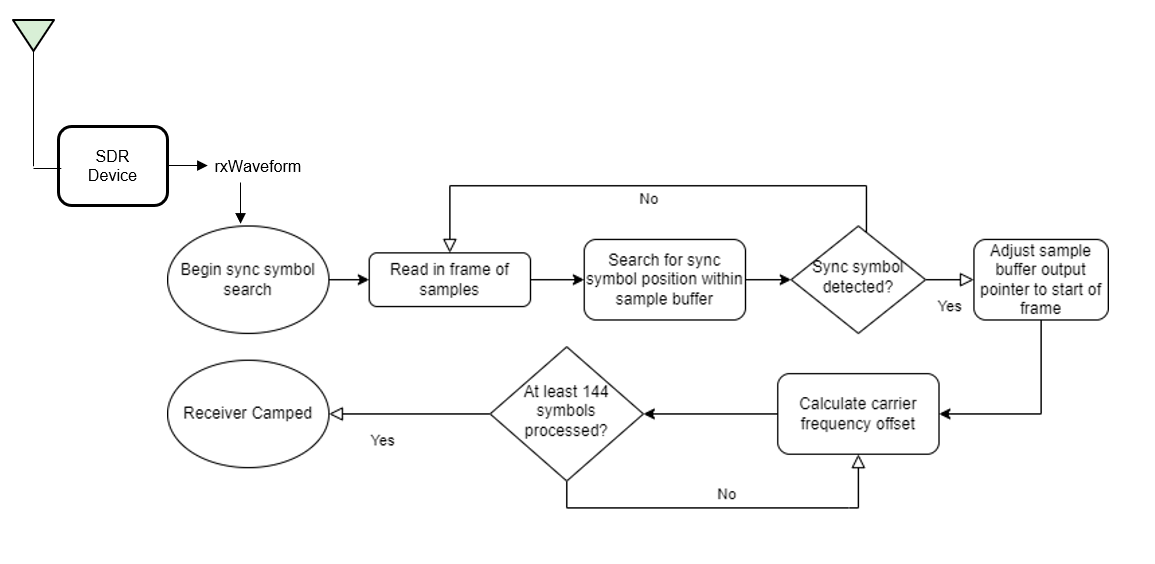

### Receiver Processing

This process is the reverse of the process that happens at the transmitter.

#### Channel Estimation and Equalization

Initially, the OFDM receiver performs channel estimation on the OFDM demodulated reference symbols. To remove the effects of time-varying fading, the receiver selects two reference symbols from adjacent frames to estimate the channel at two different points in time. The receiver then linearly interpolates the channel estimates between the two reference symbols to get the channel estimates for the header and data symbols. The `ofdmEqualize` function then equalizes the reference symbols and data symbols using the channel estimates.

#### Header Decoding

The receiver extracts and decodes the header symbols to get the data symbol parameters such as FFT length, subcarrier modulation scheme, and code rate. The receiver uses these parameters to demodulate and decode the data symbols.

#### Data Decoding

The common phase error (CPE) affects all subcarriers equally and the OFDM receiver uses the pilot symbols within the data symbols to estimate CPE. The `helperOFDMRx` function corrects the phase errors in the data symbols and the `qamdemod` function soft decodes the data subcarriers into log likelihood ratios (LLRs).

The receiver then deinterleaves the demodulated bitstream and the `vitdec` function performs maximum likelihood decoding using the Viterbi algorithm. The descrambler descrambles the decoded bits, and the `comm.CRCDetector` computes the cyclic redundancy check (CRC) and compares it with the appended CRC.

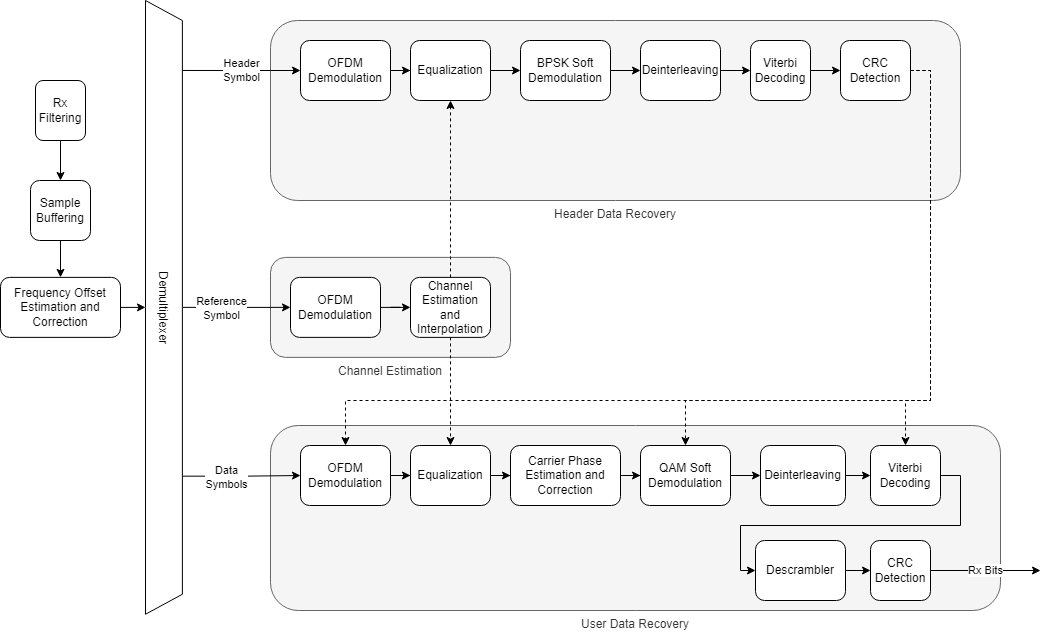

% Clear all the function data as they contain some persistent variables
clear helperOFDMRx helperOFDMRxFrontEnd helperOFDMRxSearch helperOFDMFrequencyOffset;
close all;

errorRate = comm.ErrorRate();
toverflow = 0; % Receiver overflow count
rxObj = helperOFDMRxInit(sysParam);
BER = zeros(1,dataParams.numFrames);
for frameNum = 1:dataParams.numFrames
    sysParam.frameNum = frameNum;
    [rxWaveform, ~, overflow] = radio();

    toverflow = toverflow + overflow;

    % Run the receiver front-end only when there is no overflow
    if ~overflow
        rxIn = helperOFDMRxFrontEnd(rxWaveform,sysParam,rxObj);

        % Run the receiver processing
        [rxDataBits,isConnected,toff,rxDiagnostics] = helperOFDMRx(rxIn,sysParam,rxObj);
        sysParam.timingAdvance = toff;

        % Collect bit and frame error statistics
        if isConnected
            % Continuously update the bit error rate using the |comm.ErrorRate|
            % System object
            berVals = errorRate(...
                transportBlk((1:sysParam.trBlkSize)).', ...
                rxDataBits);
            BER(frameNum) = berVals(1);
            if dataParams.printData
                % As each character in the data is encoded by 7 bits, decode the received data up to last multiples of 7
                numBitsToDecode = length(rxDataBits) - mod(length(rxDataBits),7);
                recData = char(bit2int(reshape(rxDataBits(1:numBitsToDecode),7,[]),7));
                fprintf('Received data in frame %d: %s',frameNum,recData);
            end
        end

        if isConnected && dataParams.enableScopes
            constDiag(complex(rxDiagnostics.rxConstellationHeader(:)), ...
                complex(rxDiagnostics.rxConstellationData(:)));
        end

        if dataParams.enableScopes
            spectrumAnalyze(rxWaveform);
        end
    end
end

## Establishing connection to hardware. This process can take several seconds.


.............................................................................................................
Sync symbol found.
Estimating carrier frequency offset ........
Receiver camped.
.

Received data in frame 118: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 119: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 120: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 121: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 122: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 123: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 124: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 125: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 126: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 127: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 128: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 129: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 130: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 131: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 132: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 133: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 134: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 135: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 136: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 137: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 138: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 139: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 140: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 141: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 142: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 143: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 144: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 145: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 146: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 147: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 148: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 149: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 150: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 151: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 152: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 153: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 154: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 155: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 156: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 157: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 158: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 159: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.


Received data in frame 160: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 161: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 162: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 163: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 164: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 165: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 166: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 167: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 168: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 169: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 170: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 171: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 172: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 173: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 174: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 175: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 176: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 177: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 178: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 179: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 180: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 181: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 182: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 183: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 184: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 185: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 186: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 187: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 188: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 189: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 190: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 191: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 192: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 193: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 194: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 195: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 196: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 197: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 198: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 199: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 200: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 201: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 202: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 203: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 204: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 205: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 206: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 207: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 208: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 209: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 210: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 211: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 212: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 213: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 214: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 215: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 216: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 217: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 218: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 219: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 220: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 221: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 222: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 223: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 224: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 225: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 226: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 227: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 228: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 229: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 230: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 231: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 232: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 233: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 234: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 235: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 236: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 237: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 238: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 239: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.


Received data in frame 240: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 241: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 242: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 243: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 244: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 245: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 246: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 247: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 248: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 249: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 250: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 251: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 252: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 253: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 254: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 255: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 256: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 257: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 258: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 259: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 260: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 261: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 262: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 263: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 264: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 265: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 266: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 267: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 268: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 269: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 270: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 271: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 272: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 273: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 274: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 275: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 276: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 277: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 278: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 279: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 280: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 281: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 282: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 283: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 284: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 285: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 286: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 287: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 288: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 289: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 290: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 291: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 292: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 293: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 294: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 295: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 296: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 297: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 298: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 299: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 300: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 301: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 302: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 303: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 304: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 305: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 306: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 307: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 308: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 309: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 310: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 311: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 312: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 313: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 314: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 315: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 316: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 317: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 318: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 319: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.


Received data in frame 320: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 321: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 322: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 323: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 324: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 325: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 326: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 327: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 328: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 329: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 330: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 331: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 332: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 333: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 334: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 335: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 336: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 337: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 338: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 339: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 340: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 341: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 342: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 343: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 344: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 345: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 346: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 347: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 348: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 349: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 350: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 351: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 352: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 353: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 354: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 355: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 356: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 357: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 358: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 359: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 360: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 361: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 362: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 363: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 364: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 365: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 366: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 367: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 368: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 369: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 370: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 371: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 372: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 373: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 374: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 375: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 376: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 377: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 378: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 379: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 380: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 381: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 382: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 383: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 384: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 385: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 386: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 387: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 388: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 389: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 390: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 391: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 392: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 393: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 394: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 395: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 396: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 397: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 398: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 399: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.


Received data in frame 400: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 401: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 402: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 403: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 404: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 405: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 406: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 407: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 408: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 409: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 410: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 411: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 412: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 413: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 414: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 415: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 416: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 417: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 418: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 419: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 420: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 421: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 422: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 423: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 424: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 425: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 426: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 427: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 428: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 429: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 430: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 431: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 432: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 433: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 434: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 435: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 436: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 437: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 438: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 439: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 440: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 441: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 442: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 443: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 444: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 445: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 446: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 447: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 448: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 449: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 450: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 451: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 452: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 453: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 454: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 455: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 456: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 457: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 458: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 459: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 460: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 461: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 462: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 463: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 464: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 465: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 466: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 467: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 468: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 469: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 470: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 471: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 472: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 473: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 474: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 475: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 476: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 477: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 478: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 479: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.


Received data in frame 480: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 481: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 482: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 483: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 484: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 485: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 486: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 487: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 488: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 489: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 490: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 491: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 492: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 493: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 494: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 495: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 496: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 497: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 498: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 499: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 500: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 501: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 502: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 503: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 504: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 505: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 506: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 507: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 508: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 509: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 510: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 511: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 512: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 513: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 514: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 515: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 516: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 517: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 518: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 519: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 520: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 521: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 522: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 523: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 524: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 525: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 526: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 527: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 528: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 529: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 530: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 531: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 532: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 533: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 534: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 535: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 536: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 537: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 538: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 539: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 540: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 541: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 542: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 543: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 544: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 545: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 546: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 547: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 548: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 549: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 550: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 551: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 552: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 553: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 554: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 555: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 556: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 557: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 558: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 559: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.


Received data in frame 560: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 561: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 562: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 563: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 564: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 565: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 566: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 567: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 568: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 569: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 570: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 571: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 572: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 573: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 574: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 575: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 576: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 577: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 578: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 579: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 580: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 581: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 582: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 583: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 584: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 585: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 586: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 587: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 588: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 589: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 590: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 591: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 592: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 593: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 594: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 595: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 596: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 597: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 598: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 599: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 600: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 601: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 602: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 603: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 604: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 605: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 606: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 607: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 608: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 609: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 610: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 611: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 612: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 613: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 614: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 615: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 616: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 617: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 618: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 619: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 620: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 621: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 622: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 623: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 624: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 625: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 626: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 627: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 628: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 629: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 630: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 631: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 632: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 633: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 634: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 635: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 636: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 637: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 638: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 639: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.


Received data in frame 640: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 641: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 642: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 643: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 644: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 645: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 646: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 647: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 648: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 649: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 650: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 651: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 652: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 653: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 654: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 655: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 656: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 657: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 658: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 659: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 660: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 661: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 662: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 663: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 664: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 665: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 666: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 667: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 668: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 669: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 670: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 671: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 672: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 673: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 674: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 675: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 676: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 677: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 678: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 679: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 680: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 681: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 682: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 683: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 684: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 685: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 686: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 687: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 688: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 689: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 690: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 691: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 692: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 693: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 694: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 695: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 696: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 697: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 698: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 699: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 700: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 701: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 702: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 703: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 704: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 705: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 706: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 707: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 708: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 709: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 710: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 711: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 712: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 713: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 714: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 715: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 716: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 717: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 718: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 719: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.


Received data in frame 720: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 721: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 722: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 723: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 724: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 725: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 726: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 727: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 728: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 729: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 730: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 731: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 732: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 733: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 734: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 735: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 736: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 737: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 738: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 739: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 740: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 741: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 742: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 743: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 744: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 745: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 746: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 747: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 748: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 749: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 750: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 751: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 752: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 753: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 754: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 755: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 756: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 757: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 758: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 759: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 760: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 761: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 762: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 763: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 764: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 765: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 766: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 767: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 768: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 769: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 770: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 771: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 772: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 773: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 774: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 775: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 776: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 777: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 778: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 779: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 780: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 781: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 782: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 783: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 784: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 785: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 786: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 787: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 788: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 789: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 790: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 791: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 792: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 793: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 794: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 795: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 796: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 797: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 798: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 799: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.


Received data in frame 800: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 801: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 802: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 803: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 804: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 805: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 806: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 807: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 808: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 809: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 810: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 811: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 812: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 813: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 814: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 815: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 816: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 817: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 818: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 819: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 820: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 821: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 822: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 823: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 824: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 825: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 826: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 827: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 828: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 829: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 830: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 831: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 832: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 833: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 834: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 835: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 836: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 837: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 838: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 839: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 840: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 841: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 842: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 843: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 844: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 845: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 846: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 847: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 848: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 849: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 850: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 851: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 852: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 853: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 854: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 855: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 856: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 857: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 858: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 859: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 860: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 861: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 862: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 863: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 864: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 865: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 866: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 867: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 868: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 869: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 870: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 871: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 872: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 873: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 874: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 875: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 876: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 877: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 878: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 879: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.


Received data in frame 880: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 881: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 882: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 883: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 884: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 885: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 886: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 887: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 888: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 889: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 890: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 891: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 892: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 893: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 894: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 895: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 896: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 897: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 898: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 899: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 900: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 901: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 902: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 903: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 904: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 905: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 906: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 907: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 908: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 909: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 910: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 911: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 912: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 913: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 914: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 915: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 916: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 917: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 918: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 919: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 920: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 921: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 922: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 923: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 924: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 925: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 926: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 927: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 928: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 929: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 930: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 931: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 932: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 933: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 934: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 935: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 936: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 937: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 938: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 939: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 940: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 941: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 942: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 943: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 944: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 945: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 946: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 947: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 948: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 949: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 950: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 951: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 952: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 953: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 954: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 955: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 956: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 957: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 958: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 959: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.


Received data in frame 960: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 961: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 962: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 963: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 964: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 965: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 966: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 967: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 968: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 969: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 970: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 971: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 972: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 973: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 974: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 975: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 976: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 977: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 978: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 979: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 980: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 981: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 982: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 983: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 984: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 985: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 986: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 987: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 988: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 989: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 990: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 991: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 992: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 993: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 994: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 995: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 996: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 997: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 998: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 999: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1000: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1001: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1002: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1003: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1004: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1005: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1006: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1007: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1008: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1009: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1010: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1011: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1012: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1013: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1014: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1015: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1016: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1017: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1018: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1019: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1020: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1021: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1022: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1023: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1024: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1025: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1026: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1027: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1028: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1029: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1030: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1031: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1032: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1033: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1034: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1035: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1036: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1037: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1038: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1039: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.


Received data in frame 1040: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1041: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1042: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1043: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1044: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1045: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1046: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1047: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1048: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1049: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1050: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1051: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1052: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1053: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1054: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1055: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1056: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1057: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1058: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1059: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1060: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1061: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1062: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1063: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1064: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1065: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1066: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1067: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1068: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1069: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1070: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1071: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1072: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1073: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1074: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1075: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1076: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1077: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1078: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1079: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1080: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1081: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1082: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1083: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1084: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1085: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1086: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1087: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1088: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1089: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1090: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1091: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1092: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1093: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1094: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1095: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1096: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1097: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1098: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1099: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1100: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1101: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1102: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1103: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1104: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1105: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1106: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1107: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1108: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1109: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1110: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1111: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1112: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1113: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1114: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 1115: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

% Display the mean BER value across all frames
fprintf('Simulation complete!\nAverage BER = %d',mean(BER))
release(radio);

## Troubleshooting

#### **No data in any frame**

Problem

- The receiver continuously receives no data in any frame.

Possible causes

- Transmitter is not running

- Too high or too low transmitter and receiver gains

- Too many under-runs at the transmitter

Possible solutions

- Ensure that the transmitter is running

- Adjust the transmitter and receiver gains

- Adjust the frame length to make sure there are very few under-runs at the transmitter.

#### **Header CRC fails**

Problem

- Even when synchronization and receiver camping are successful, the header CRC check fails.

Possible causes

-  Insufficient compensation of clock frequency offset.

Possible solutions

- The frequency compensation algorithm measures and corrects the frequency and phase offset for each frame, and it can estimate the correct offset up to half of the subcarrier spacing. You can calibrate the frequency offset to resolve this error.

For USRP radios, you can determine the frequency offset by sending a tone at a known frequency from the transmitter and measure the offset between the transmitted and received frequency. Apply the measured offset to the center frequency of `comm.SDRuReceiver` receiver System object.

For ADALM-Pluto radios, run the [Frequency offset calibration with ADALM-Pluto Radio in Simulink](docid:plutoradio_ug#mw_baa863fb-d239-4495-baf9-eb6864e0f592) example to get the frequency offset. Apply the measured offset to the center frequency of the `comm.SDRRxPluto`  receiver System object.

#### **Data decoding fails**

Problem

- The data decoding fails even when the header CRC decoding is successful.

Possible causes

- Data overflow at the receiver

- Inaccurate channel estimate due to exceeding frame length.

Possible solutions

-  Adjust the frame size

- Change the number of symbols per frame to minimize the frame length.

## Further Exploration

You can use an external clock source or GPSDO with the radios to try smaller subcarrier spacing of 15 KHz with smaller bandwidths such as 1.4 MHz (LTE bandwidths) or higher FFTLengths such as 256. 

This example uses burst mode in the radios to receive the data, with the burst size set to the number of frames. You can further explore receiving the data using the radios in non-burst mode.

*Copyright 2023-2025 The MathWorks, Inc.*